# **IO421-1 LVDT/RVDT Measurement**

This example shows you how to perform a test with the IO421-1 I/O module to verify the LVDT/RVDT measurement functionality of the 4-wire wiring mode.

The IO421 I/O module has three independent slots. Each slot can be populated with a function-specific I/O sub-module. The IO421-1 sub-module measures up to four Linear or Rotary Variable Differential Transformers. Each channel has separate inputs for the reference (excitation) and the A/B signals.

The Simulink model used in this example features the [IO421 LVDT read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io421_lvdtrvdt_read) block.

## Test Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO421-1 I/O module installed

- Connector cable from the I/O module to the terminal board

- 78-pin terminal board with jumper wires

- External signal generator

### Test Setup

LVDTs and RVDTs are electromagnetic displacement transducers designed to provide output voltages proportional to linear and rotary displacement, respectively. The primary (Ch 01 Rh-RL) is excited with a sine-wave voltage, the frequency of which, depending on the design, may be from 400 [Hz] to over 10 [kHz]. The secondary windings (Ch 1 A-B) are wired in a series-opposing configuration and are excited with an Amplitude Modulated sine-wave voltage.

The following wiring is required (this example is for the LD in slot 1):

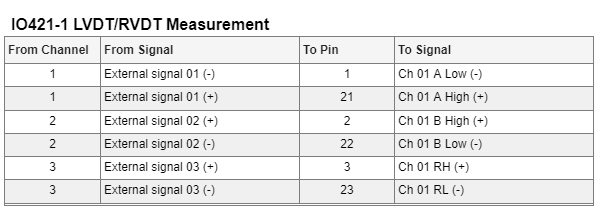

The full pin mapping of the IO421-1 can be found here: [IO421 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io421_pin_mapping)

## Open Simulink Model

 
modelName = 'sgMdl_IO421_1_LVDTMeasurementTest';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

When the movable core (See [IO421 Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io421_usage_notes)) is equidistant between the primary and secondary windings, the resulting voltage, measured across the secondary winding, is zero. A core displacement on either side of this zero position will generate an AC secondary voltage that will change linearly over a specified range of movement. The phase of this secondary AC voltage will be nominally either zero degrees or 180 degrees (with respect to the AC primary voltage reference excitation), depending on the direction in which the core has moved from the "zero position".

  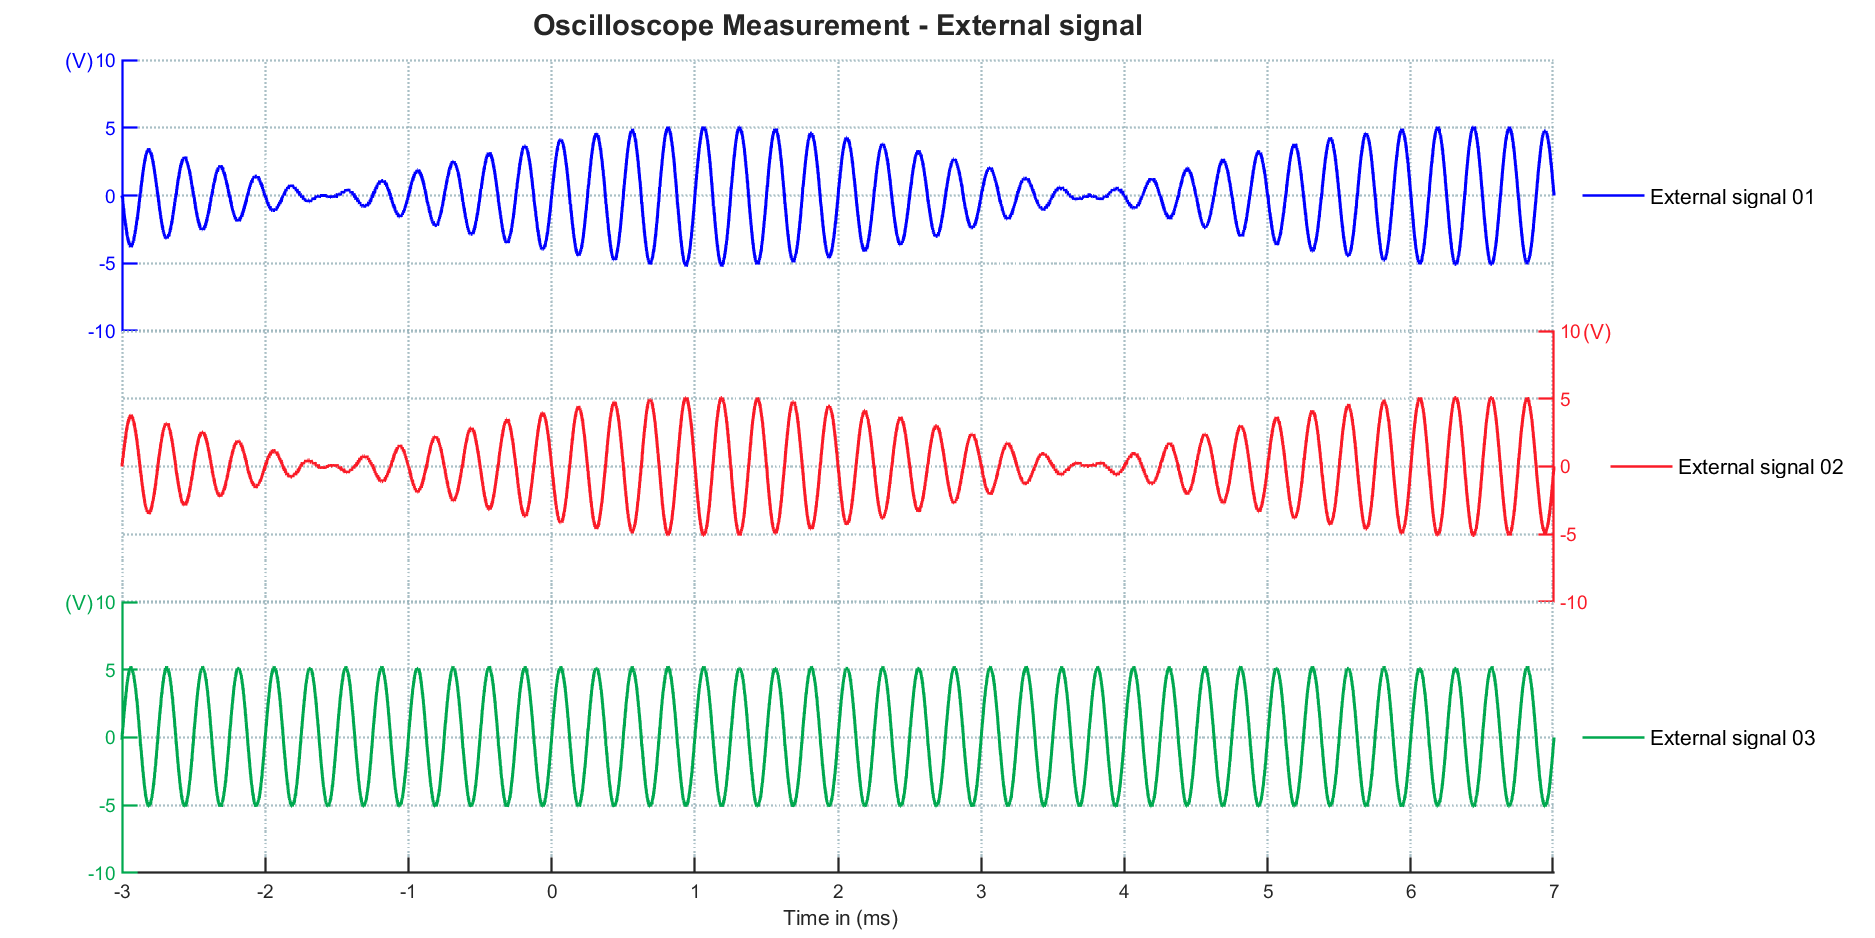

This AC secondary voltage is fed into a phase-sensitive detector. The output is a DC voltage whose polarity depends on its phase, and whose amplitude is proportional to the amount of movement from zero.

Open the Simulink scope connected to the [IO421 LVDT read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io421_lvdtrvdt_read) block and check if the signals displayed correspond to the signals created by the LVDT read block.

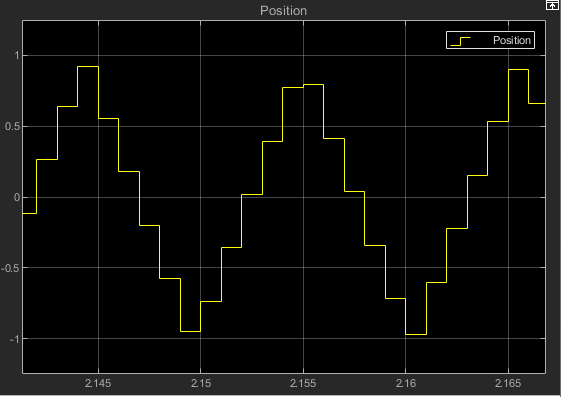

## Additional References

- [IO421 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io421)